# DATA PRE-PROCESSING WITH MATLAB

**Author:** Abisoye Akinloye

*Connect with him on *[*Linkedin*](https://www.linkedin.com/in/abisoye-akinloye)*, Twitter, & YouTube *

## Data Processing

    It is an important steps in building Machine Learning model. If not done, the ML model wouldn't work effectively.

### Importing Data

    There are two ways of importing data in MATLAB:

- From the `Home` tab `Import Data` option

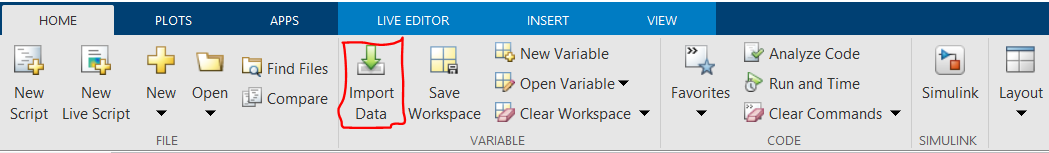

- Reading the data as table, csv, or delimiter method. 

**    Note:**

- If the imported data comprise of missing numerial value, it is replaced with `NaN (Not a number)`

- If the imported data comprise of missing textual value, it is replaced with `'' (Empty character)`

- If the imported data comprise of missing categorical value, it is replaced with `<undefined> `

- Machine learning models require `table` data type

% import data
data = readtable("data\data_1.csv","VariableNamingRule","preserve");

% check the first 5 rows of the data
data(1:5,:)

ans = 5×4 table
     Location     Age    Annual Salary       Opinion   
    __________    ___    _____________    _____________

    {'US'    }    40         72000        {'not liked'}
    {'Asia'  }    25         48000        {'not liked'}
    {'Africa'}    30         54000        {'not liked'}
    {'Asia'  }    35         61000        {'not liked'}
    {'Africa'}    44           NaN        {'Liked'    }


The data above show the opinion of different buyers of a goods based on their location, age, annual salary.

- The opinion is the `dependent` variable

- The other features are the `independent` variables.

### Handling Missing Numerical Data

There are methods of handling missing data. They are:

- Deleting rows or colums with missing value.

- Replacing the missing data with the `mean/median` of the column for numerical data.

- To check if there is a missing value, use the built-in function.

#### **Deleting rows or columns with missing values**

% delete rows of missing value
no_missing_row_data = rmmissing(data)

no_missing_row_data = 8×4 table
     Location     Age    Annual Salary       Opinion   
    __________    ___    _____________    _____________

    {'US'    }    40         72000        {'not liked'}
    {'Asia'  }    25         48000        {'not liked'}
    {'Africa'}    30         54000        {'not liked'}
    {'Asia'  }    35         61000        {'not liked'}
    {'US'    }    33         58000        {'Liked'    }
    {'US'    }    40         79000        {'Liked'    }
    {'Africa'}    55         83000        {'not liked'}
    {'US'    }    35         67000        {'Liked'    }


% delete columns with missing values
no_missing_col_data = rmmissing(data,2);

% get first 5 rows of the data
no_missing_col_data(1:5,:)

ans = 5×2 table
     Location        Opinion   
    __________    _____________

    {'US'    }    {'not liked'}
    {'Asia'  }    {'not liked'}
    {'Africa'}    {'not liked'}
    {'Asia'  }    {'not liked'}
    {'Africa'}    {'Liked'    }


**Note:**

- By default using `rmmissing()` will remove rows with missing value

- Add `argument/dimension ``2` to remove column with missing values. 

- Deleting columns or rows can be more dangerous to the data, however, it is not recommended.

- If the data is very large and the missing value is not very significant, you could delete the rows.

- Deleting columns should be generally **avoided** and should only be considered when numbers of features are many.

- For example, in text categorization and email classification problems.

**Deleting Rows or Columns with Relative percentage of missing value**

- Add the `MinNumMissing` argument to the `rmmissing()`

% import and show the data
data2 = readtable("data\data_2.csv","VariableNamingRule","preserve");

ans = 5×4 table
     Location     Age    Annual Salary       Opinion   
    __________    ___    _____________    _____________

    {'US'    }     40        72000        {'not liked'}
    {'Asia'  }     25        48000        {'not liked'}
    {'Africa'}     30          NaN        {'not liked'}
    {'Asia'  }     35        61000        {'not liked'}
    {'Africa'}    NaN          NaN        {'Liked'    }


data2(1:5,:)
% 2 -> least number of missing value in a row 

rel_data = 9×4 table
     Location     Age    Annual Salary       Opinion   
    __________    ___    _____________    _____________

    {'US'    }     40        72000        {'not liked'}
    {'Asia'  }     25        48000        {'not liked'}
    {'Africa'}     30          NaN        {'not liked'}
    {'Asia'  }     35        61000        {'not liked'}
    {'US'    }     33        58000        {'Liked'    }
    {'Asia'  }    NaN        52000        {'not liked'}
    {'US'    }     40        79000        {'Liked'    }
    {'Africa'}     55        83000        {'not liked'}
    {'US'    }     35        67000        {'Liked'    }


rel_data = rmmissing(data2,'MinNumMissing',2)
% 2 -> least number of missing value in a column to be deleted
% N.B: It is not recommended as the necessary features have been deleted

rel_data_del = 10×2 table
     Location        Opinion   
    __________    _____________

    {'US'    }    {'not liked'}
    {'Asia'  }    {'not liked'}
    {'Africa'}    {'not liked'}
    {'Asia'  }    {'not liked'}
    {'Africa'}    {'Liked'    }
    {'US'    }    {'Liked'    }
    {'Asia'  }    {'not liked'}
    {'US'    }    {'Liked'    }
    {'Africa'}    {'not liked'}
    {'US'    }    {'Liked'    }


rel_data_del = rmmissing(data2,2,"MinNumMissing",2)

#### Replacing missing value with Mean

- use `mean()` and add `omitnan` argument to compute the mean.

- Use  `fillmissing() `to fill the missing value

- The `fillmissing` methods are: `constant, next, previous, nearest`, and so on.

% calculate mean omitting NaN
age_mean = mean(data.Age,'omitnan');

% fill missing age with a constant value -> mean
no_missing_age = fillmissing(data.Age,"constant",age_mean);

% copy the data (not necessary)
copy_data = data;
% replace the age column with age with no missing value
copy_data.Age = no_missing_age
% replace missing value in salary column

copy_data = 10×4 table
     Location      Age      Annual Salary       Opinion   
    __________    ______    _____________    _____________

    {'US'    }        40        72000        {'not liked'}
    {'Asia'  }        25        48000        {'not liked'}
    {'Africa'}        30        54000        {'not liked'}
    {'Asia'  }        35        61000        {'not liked'}
    {'Africa'}        44          NaN        {'Liked'    }
    {'US'    }        33        58000        {'Liked'    }
    {'Asia'  }    37.444        52000        {'not liked'}
    {'US'    }        40        79000        {'Liked'    }
    {'Africa'}        55        83000        {'not liked'}
    {'US'    }        35        67000        {'Liked'    }


salary_mean = mean(data.("Annual Salary"), 'omitnan');
no_missing_salary = fillmissing(data.("Annual Salary"),"constant",salary_mean);

format shortG
copy_data.("Annual Salary") = no_missing_salary

### Handling missing textual data

Textual data cannot be replaced with the `mean. `You cannot take the mean of non-numerical value. Hence, find and replace by most frquently occuring value.

- Covert to categorical data type `categorical()`

- Find the most occuring value `mode()`

- Fill with the most occuring value.

% import the data

copy_data = 10×4 table
     Location      Age      Annual Salary       Opinion   
    __________    ______    _____________    _____________

    {'US'    }        40        72000        {'not liked'}
    {'Asia'  }        25        48000        {'not liked'}
    {'Africa'}        30        54000        {'not liked'}
    {'Asia'  }        35        61000        {'not liked'}
    {'Africa'}        44        63778        {'Liked'    }
    {'US'    }        33        58000        {'Liked'    }
    {'Asia'  }    37.444        52000        {'not liked'}
    {'US'    }        40        79000        {'Liked'    }
    {'Africa'}        55        83000        {'not liked'}
    {'US'    }        35        67000        {'Liked'    }


data3 = readtable("data\data_3.csv","VariableNamingRule","preserve");
data3(1:5,:)
% first convert to categorical data type
data3.Opinion = categorical(data3.Opinion);

% find the mode
freq_opinion = mode(data3.Opinion);
% fill missing value with most frequent
no_missing_opinion = fillmissing(data3.Opinion,"constant",cellstr(freq_opinion));

ans = 5×4 table
     Location     Age    Annual Salary       Opinion   
    __________    ___    _____________    _____________

    {'US'    }    40         72000        {'not liked'}
    {'Asia'  }    25         48000        {0×0 char   }
    {'Africa'}    30         54000        {'not liked'}
    {'Asia'  }    35         61000        {'not liked'}
    {'Africa'}    44           NaN        {'Liked'    }


data3.Opinion = no_missing_opinion;
data3(1:5,:)

### Features scaling

% import the data
data4 = readtable("D:\Projects\MATLAB\MATLAB-from-beginner-to-advanced\ML\Part 3\data\data_4.csv","VariableNamingRule",'preserve');
data4(1:5,:)

Considering the features (Age and Annual Salary), it is obvious that both are not on the same scale/range. The value is of annual salary is much greater than age. This will however lead to issues in the Machine Learning model. When those features are fed into ML model, it assumes that age value is negligible; thereby making prediction based on annual salary only.

Hence, you can transform the features into the same scale for instance  `-1 or +1` whereby the minimum value can rep -1 while the maximum represents +1. There are different types of features scaling, but the most often used are **Standardization** and **Normalization.  **

#### **Standardization**

It transform features from the range of `-1 to +1`


$$\mathbf {x_{transformed} = \frac{x - mean(x)} {standard \thinspace deviation(x)}}$$


#### Normalization

It transform features from the range of `0 to +1`


$$\mathbf { x_{transformed} = \frac{x - min(x)} {max(x) - min(x)}}}$$


% standardize feature scaling for age
standardized_age = standardize(data4.Age);
data4.Age = standardized_age;


ans = 5×4 table
     Location     Age    Annual Salary     Opinion 
    __________    ___    _____________    _________

    {'US'    }    40         72000        not liked
    {'Asia'  }    25         48000        not liked
    {'Africa'}    30         54000        not liked
    {'Asia'  }    35         61000        not liked
    {'Africa'}    44           NaN        Liked    


% standardized feature scaling for annual salary
standardized_salary = standardize(data4.("Annual Salary"));
data4.("Annual Salary") = standardized_salary;

% view the data

ans = 5×4 table
     Location     Age    Annual Salary       Opinion   
    __________    ___    _____________    _____________

    {'US'    }    40         72000        {'not liked'}
    {'Asia'  }    25         48000        {'not liked'}
    {'Africa'}    30         54000        {'not liked'}
    {'Asia'  }    35         61000        {'not liked'}
    {'Africa'}    44         63777        {'Liked'    }


data4
% Normalize features scaling for age
normalized_age = normalize(data4.Age);
data_norm =data4;
data_norm.Age = normalized_age;

% Normalize features scaling for annual salary
normalized_salary = normalize(data4.("Annual Salary"));
data_norm.("Annual Salary") = normalized_salary

### Handling Outlier

An outlier is a value that has huge/abnormal deviation from other values. It may be due to variabiltiy in measurement or it may indicate an experimental error. It is important to get rid of the outliers in data before passing it to the Machine Learning algorithm.

- Use `isoutlier()` to check if there is an outlier.

- **How to: **Delete Outlier row, Fill outlier.

#### Techniques for handling outliers

- Calculate** Z-Score**

                
$$Z=\frac{x-\mu }{\sigma }$$


$\mu \;\mathrm{represents}\;\mathrm{mean},\sigma \;\mathrm{represents}\;\mathrm{standard}\;\mathrm{deviation}\ldotp$ **N.B: **If the data is deviated more/less than 3-standard deviation, it is possibly an Outlier.

- Median Absolute Deviation

                
$$\mathrm{MAD}=\mathrm{median}\left(|x\;-\;\mathrm{median}\left(x\right)|\right)$$


By default, an outlier is a value that is more than three scaled median absolute deviation (MAD) away from the median.

data5 = readtable("data\data_5.csv","VariableNamingRule","preserve");
data5(1:3,:)
% check for outliers
% it is applied to numerical data only
sum(isoutlier(data5.Age))
% check the outlier
data5.Age(isoutlier(data5.Age)>0)

data4 = 10×4 table
     Location        Age       Annual Salary       Opinion   
    __________    _________    _____________    _____________

    {'US'    }      0.31675         0.71102     {'not liked'}
    {'Asia'  }      -1.5106         -1.3644     {'not liked'}
    {'Africa'}     -0.90152        -0.84552     {'not liked'}
    {'Asia'  }     -0.29238         -0.2402     {'not liked'}
    {'Africa'}      0.80405     -6.0532e-05     {'Liked'    }
    {'US'    }     -0.53604        -0.49962     {'Liked'    }
    {'Asia'  }    -0.048731         -1.0185     {'not liked'}
    {'US'    }      0.31675          1.3163     {'Liked'    }
    {'Africa'}       2.1441          1.6622     {'not liked'}
    {'US'    }     -0.29238         0.27865     {'Liked'    }


**How MATLAB detect an Outlier?**

By default, MATLAB uses the information of the `median of a data` to determine its outlier. It will discard values **3times** greater or lesser from the median.

The methods are:

- mean

- median

- movmean

**Deleting Outliers**

% delete outlier using logical indexing
outliers = isoutlier(data5.Age);

data5 = data5(~outliers,:)

**Filling Outliers (Recommended)**

The fill outlier methods are:

- central

- linear

- previous

- next and so on.

data_fill = readtable("data\data_5.csv","VariableNamingRule","preserve");

% fill with center -> median
Age = filloutliers(data_fill.Age,"center");

data_norm = 10×4 table
     Location       Age      Annual Salary       Opinion   
    __________    _______    _____________    _____________

    {'US'    }        0.5       0.68571       {'not liked'}
    {'Asia'  }          0             0       {'not liked'}
    {'Africa'}    0.16667       0.17143       {'not liked'}
    {'Asia'  }    0.33333       0.37143       {'not liked'}
    {'Africa'}    0.63333       0.45077       {'Liked'    }
    {'US'    }    0.26667       0.28571       {'Liked'    }
    {'Asia'  }        0.4       0.11429       {'not liked'}
    {'US'    }        0.5       0.88571       {'Liked'    }
    {'Africa'}          1             1       {'not liked'}
    {'US'    }    0.33333       0.54286       {'Liked'    }



% the default is median, you can specify using the 3rd argument.
data_fill.Age = Age

### Encoding Categorical data

Since the machine learning models are based on mathematical formula, the categorical data are conveted into numerical data. 

data_fill

You cannot assign any number value to represent a `nominal` categorical data but you can for an `ordinal` categorical data.

For instance, if Us = 0, Asia = 1, and Africa = 2. The machine learning model would assume that `Africa > Asia > Us` but for ordinal categorical data; poor = 1, good = 2, excellent = 3. That is, `excellent > good > poor`.

Another example of the ordinal data is grades:** A, B, C, D, E, F**. A = 5, B = 4, C = 3,  D = 2, E = 1, F = 0.

encoding = readtable("data\encode.csv","VariableNamingRule","preserve")

ans = 3×4 table
     Location     Age    Annual Salary       Opinion   
    __________    ___    _____________    _____________

    {'US'    }    40         72000        {'not liked'}
    {'Asia'  }    25         48000        {'not liked'}
    {'Africa'}    30         54000        {'not liked'}


#### Implementing Encoding of Nominal data type with Matlab Algorithm

- MATLAB provides a function `ismember()`

% To check if a datatype is a member 
mem = ismember(data5.Location,'Asia');

ans = 0

% convert the logical value to double
mem_arr = double(mem);


ans =

  0×1 empty double column vector




% convert the array to table
% N.B: The variable name must be converted to cell
mem_table = array2table(mem_arr,'VariableNames',{'France'})
encoded_data = categorical_encoding(data5,data5.Location)
% delete the 'Location' feature since it has been encoded
encoded_data.Location = []

**N.B:** Having encoded the Location column, the next categorical data is the **Opinion.** Make sure the variables fulfil the convention of variable naming.

- No space between compound words; use snake or camel case instead.

- Special charater or number shouldn't start the naming

% save the encoded_data to modify the opinion to fulfil conventional variable naming

% notice the hyphen in between 'not_liked'
data_en = readtable('encoded_data.csv','VariableNamingRule','preserve')

data5 = 10×4 table
     Location     Age    Annual Salary       Opinion   
    __________    ___    _____________    _____________

    {'US'    }    40         72000        {'not liked'}
    {'Asia'  }    25         48000        {'not liked'}
    {'Africa'}    30         54000        {'not liked'}
    {'Asia'  }    35         61000        {'not liked'}
    {'Africa'}    44         63777        {'Liked'    }
    {'US'    }    33         58000        {'Liked'    }
    {'Asia'  }    37         52000        {'not liked'}
    {'US'    }    40         79000        {'Liked'    }
    {'Africa'}    36         83000        {'not liked'}
    {'US'    }    35         67000        {'Liked'    }


#### Implementing Encoding of Ordinal data type with Matlab Algorithm

data6 = readtable("../data/data_6.csv",'VariableNamingRule','preserve')
% encode the yearly income
yearlyIncome_encode = categorical_ordinal_encode(data6.("Yearly Income"),{'Low','Average','High','Very High'},[1,2,3,5]);
yearlyIncome_encode', data6.("Yearly Income")'
data6_copy = data6;
data6_copy.("Yearly Income") = yearlyIncome_encode

**Function for encoding ordinal categorical data.**

### Count Fequency Encoding

It can also be used to handle nominal categorical data using the frequency of occurence.

data6

data_fill = 10×4 table
     Location     Age    Annual Salary       Opinion   
    __________    ___    _____________    _____________

    {'US'    }    40         72000        {'not liked'}
    {'Asia'  }    25         48000        {'not liked'}
    {'Africa'}    30         54000        {'not liked'}
    {'Asia'  }    35         61000        {'not liked'}
    {'Africa'}    44         63777        {'Liked'    }
    {'US'    }    33         58000        {'Liked'    }
    {'Asia'  }    37         52000        {'not liked'}
    {'US'    }    40         79000        {'Liked'    }
    {'Africa'}    36         83000        {'not liked'}
    {'US'    }    35         67000        {'Liked'    }


tabulate(data6.Refund);
[row, col] = size(tabulate(data6.Refund));
size(data6.Refund,1);


data_fill = 10×4 table
     Location     Age    Annual Salary       Opinion   
    __________    ___    _____________    _____________

    {'US'    }    40         72000        {'not liked'}
    {'Asia'  }    25         48000        {'not liked'}
    {'Africa'}    30         54000        {'not liked'}
    {'Asia'  }    35         61000        {'not liked'}
    {'Africa'}    44         63777        {'Liked'    }
    {'US'    }    33         58000        {'Liked'    }
    {'Asia'  }    37         52000        {'not liked'}
    {'US'    }    40         79000        {'Liked'    }
    {'Africa'}    36         83000        {'not liked'}
    {'US'    }    35         67000        {'Liked'    }


% algorithm

freq_encode = frequency_count_encoder(data6,data6.Refund,"RefundEncode")

encoding = 10×6 table
    Age    Annual Salary       Opinion       Africa    Asia    Us
    ___    _____________    _____________    ______    ____    __

    40         72000        {'not liked'}      0        0      1 
    25         48000        {'not liked'}      0        1      0 
    30         54000        {'not liked'}      1        0      0 
    35         61000        {'not liked'}      0        1      0 
    44         63777        {'Liked'    }      1        0      0 
    33         58000        {'Liked'    }      0        0      1 
    37         52000        {'not liked'}      0        1      0 
    40         79000        {'Liked'    }      0        0      1 
    36         83000        {'not liked'}      1        0      0 
    35         67000        {'Liked'    }      

mem_table = 9×1 table
    France
    ______

      0   
      1   
      0   
      1   
      0   
      0   
      1   
      0   
      0   


encoded_data = 9×7 table
    Africa    Asia    US     Location     Age    Annual Salary       Opinion   
    ______    ____    __    __________    ___    _____________    _____________

      0        0      1     {'US'    }    40         72000        {'not liked'}
      0        1      0     {'Asia'  }    25         48000        {'not liked'}
      1        0      0     {'Africa'}    30         54000        {'not liked'}
      0        1      0     {'Asia'  }    35         61000        {'not liked'}
      1        0      0     {'Africa'}    44         63777        {'Liked'    }
      0        0      1     {'US'    }    33         58000        {'Liked'    }
      0        1      0     {'Asia'  }    37         52000        {'not liked'}
      0        0

encoded_data = 9×6 table
    Africa    Asia    US    Age    Annual Salary       Opinion   
    ______    ____    __    ___    _____________    _____________

      0        0      1     40         72000        {'not liked'}
      0        1      0     25         48000        {'not liked'}
      1        0      0     30         54000        {'not liked'}
      0        1      0     35         61000        {'not liked'}
      1        0      0     44         63777        {'Liked'    }
      0        0      1     33         58000        {'Liked'    }
      0        1      0     37         52000        {'not liked'}
      0        0      1     40         79000        {'Liked'    }
      0        0      1     35         67000        {'Liked'    }


data_en = 9×6 table
    Africa    Asia    US    Age    Annual Salary       Opinion   
    ______    ____    __    ___    _____________    _____________

      0        0      1     40         72000        {'not_liked'}
      0        1      0     25         48000        {'not_liked'}
      1        0      0     30         54000        {'not_liked'}
      0        1      0     35         61000        {'not_liked'}
      1        0      0     44         63777        {'Liked'    }
      0        0      1     33         58000        {'Liked'    }
      0        1      0     37         52000        {'not_liked'}
      0        0      1     40         79000        {'Liked'    }
      0        0      1     35         67000        {'Liked'    }


data6 = 10×4 table
    Refund     Marital Status    Yearly Income     Cheat 
    _______    ______________    _____________    _______

    {'Yes'}     {'Single'  }     {'High'     }    {'No' }
    {'No' }     {'Married' }     {'Very High'}    {'No' }
    {'No' }     {'Single'  }     {'Average'  }    {'No' }
    {'Yes'}     {'Married' }     {'High'     }    {'No' }
    {'No' }     {'Divorced'}     {'Low'      }    {'Yes'}
    {'No' }     {'Married' }     {'Low'      }    {'No' }
    {'Yes'}     {'Divorced'}     {'High'     }    {'No' }
    {'No' }     {'Single'  }     {'Average'  }    {'Yes'}
    {'No' }     {'Married' }     {'Average'  }    {'No' }
    {'No' }     {'Single'  }     {'Average'  }    {'Yes'}


ans =      3     5     2     3     1     1     3     2     2     2


ans = 1×10 cell array
    {'High'}    {'Very High'}    {'Average'}    {'High'}    {'Low'}    {'Low'}    {'High'}    {'Average'}    {'Average'}    {'Average'}


data6_copy = 10×4 table
    Refund     Marital Status    Yearly Income     Cheat 
    _______    ______________    _____________    _______

    {'Yes'}     {'Single'  }           3          {'No' }
    {'No' }     {'Married' }           5          {'No' }
    {'No' }     {'Single'  }           2          {'No' }
    {'Yes'}     {'Married' }           3          {'No' }
    {'No' }     {'Divorced'}           1          {'Yes'}
    {'No' }     {'Married' }           1          {'No' }
    {'Yes'}     {'Divorced'}           3          {'No' }
    {'No' }     {'Single'  }           2          {'Yes'}
    {'No' }     {'Married' }           2          {'No' }
    {'No' }     {'Single'  }           2          {'Yes'}


data6 = 10×4 table
    Refund     Marital Status    Yearly Income     Cheat 
    _______    ______________    _____________    _______

    {'Yes'}     {'Single'  }     {'High'     }    {'No' }
    {'No' }     {'Married' }     {'Very High'}    {'No' }
    {'No' }     {'Single'  }     {'Average'  }    {'No' }
    {'Yes'}     {'Married' }     {'High'     }    {'No' }
    {'No' }     {'Divorced'}     {'Low'      }    {'Yes'}
    {'No' }     {'Married' }     {'Low'      }    {'No' }
    {'Yes'}     {'Divorced'}     {'High'     }    {'No' }
    {'No' }     {'Single'  }     {'Average'  }    {'Yes'}
    {'No' }     {'Married' }     {'Average'  }    {'No' }
    {'No' }     {'Single'  }     {'Average'  }    {'Yes'}


  Value    Count   Percent
    Yes        3     30.00%
     No        7     70.00%


freq_encode = 10×5 table
    Refund     Marital Status    Yearly Income     Cheat     RefundEncode
    _______    ______________    _____________    _______    ____________

    {'Yes'}     {'Single'  }     {'High'     }    {'No' }         3      
    {'No' }     {'Married' }     {'Very High'}    {'No' }         7      
    {'No' }     {'Single'  }     {'Average'  }    {'No' }         7      
    {'Yes'}     {'Married' }     {'High'     }    {'No' }         3      
    {'No' }     {'Divorced'}     {'Low'      }    {'Yes'}         7      
    {'No' }     {'Married' }     {'Low'      }    {'No' }         7      
    {'Yes'}     {'Divorced'}     {'High'     }    {'No' }         3      
    {'No' }     {'Single'  }     {'Average'  }    {'Yes'}         7      
    {'No' }     {'Married' }     {'Average'  }    {'No' }       